# **TRANSIENT STATE**

*Cmmnd-T to uncomment , Cmmnd-/ to comment *

*Some of the below functions are user defined and may not work when this code is copied, although I have tried to ensure function names give the gist of what the function is doing (All functions can be seen on *[*Github*](https://github.com/rohans0509/ELL202/) )

clear;

## Set values of variables

[V1, V2, R1, R2, R3, C1, C2]=deal(1,3,3,6,5,1,2);

conductances=reciprocal([R1 R2 R3]); %returns cell of 1./array

[G1 G2 G3]=deal(conductances{:});

## Initialise symbols

syms vc1(t)
syms vc2(t)
syms ir(t)

## Evaluate at time

t=7;

## Optional Check 

Uncomment if you want to check if you've written the matrices correctly in terms of variables

% syms V1 V2 G1 G2 G3 C1 C2

##  First order

** Short-Cut** method

% tau=(L1+L2)/R;
% initial=V1/(R)*(L1)/(L1+L2);
% final=V1/R;
% ir=final+(initial-final)*exp(-t/tau)

**Advanced **method to solve 1st order ode. Express in the form of ***Y'=AY+B ***

% Y0=0
% Y=vc
% A=4
% B=5
% [vc1]=solvediff(Y,A,B,Y0) % % % Solves state space equation
% double(subs(vc1))

## Second Order

Express the equation in the form of ***Y'=AY+B***  using KVLs/KCLs.

% Y=[vc1;vc2];
% A=[(-1/(R1*C1)-1/(R2*C1)),(1/(R2*C1));(1/(R2*C2)),(-1/(R2*C2)-1/(R3*C2))]
% B=[V1/(C1*R1);V2/(C2*R3)]
% Y0=[0;0];
% [vc1,vc2]=solvediff(Y,A,B,Y0) % % % Solves state space equation
% double(subs(vc1)) 
% double(subs(vc2))

## Laplace Transform

                                                                                                      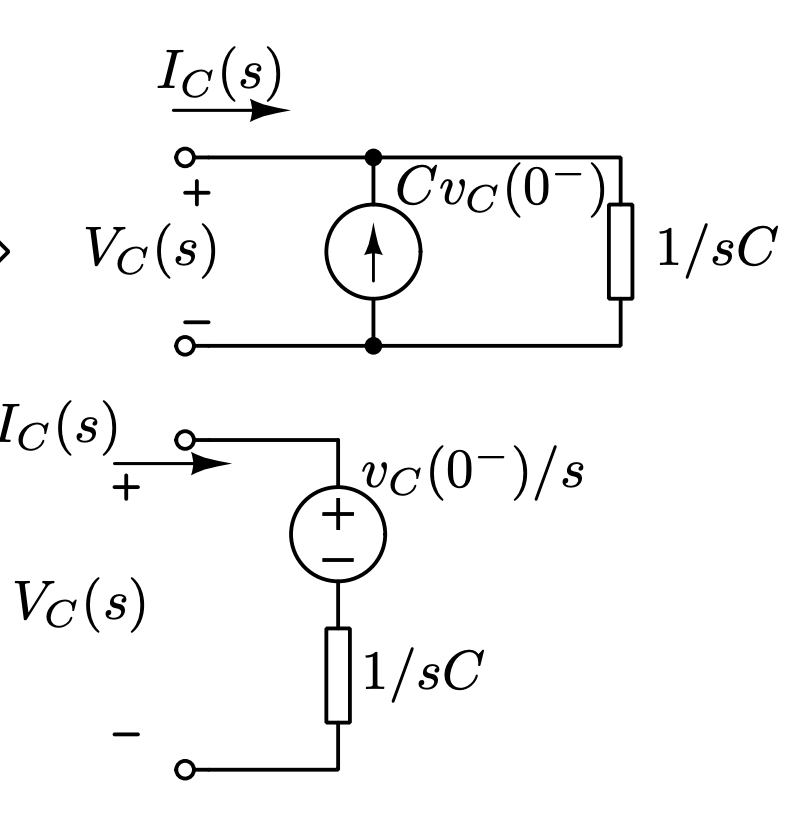                          

                                                                                                          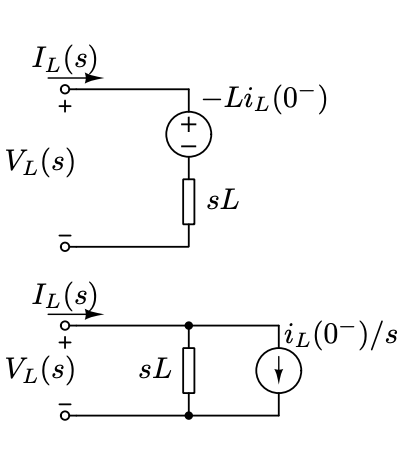

% syms s
% mat=[(G1+s*C1+G2),(-G2);(-G2),(G3+s*C2+G2)]
% out=[V1*G1/s;V2*G3/s]
% V=mat^-1*out
% solution=simplify(rewrite(ilaplace(V(1)),'exp'))
% double(subs(solution))

## Miscellaneous